This model uses transfer learning to train a deep network that can classify images of flowers into one of 12 species.

## Get training images

flowerds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels));

## Create a network by modifying AlexNet

Get the layers from AlexNet

net = alexnet;
layers = net.Layers;

Modify the classification and output layers

layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;

## Set training algorithm options

Lower the learning rate for transfer learning

options = trainingOptions('sgdm','InitialLearnRate', 0.001);

## Perform training

[flowernet,info] = trainNetwork(trainImgs, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:14 |       15.63% |       5.5775 |          0.0010 |
|      13 |          50 |       00:05:15 |       99.22% |       0.0153 |          0.0010 |
|      25 |         100 |       00:09:57 |      100.00% |       0.0044 |          0.0010 |
|      30 |         120 |       00:11:50 |      100.00% |       0.0016 |          0.0010 |
|========================================================================================|


## Use the trained network to classify test images

testpreds = classify(flowernet,testImgs);

## Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.8438

Visualize the confusion matrix

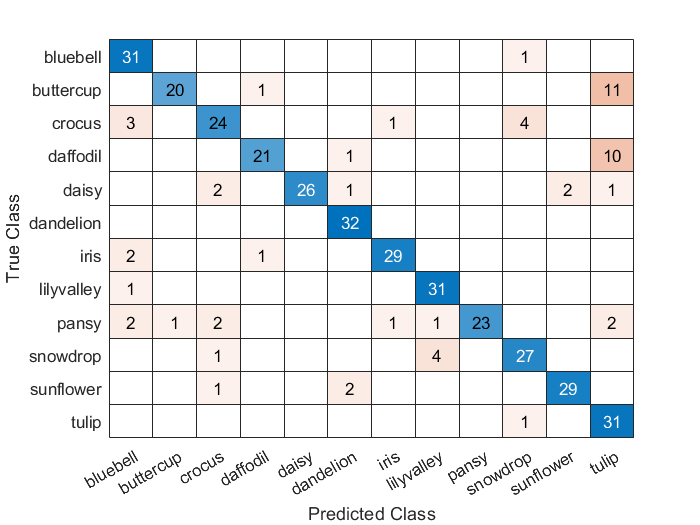

confusionchart(testImgs.Labels,testpreds);